Elephant step vibration detection in using MLOG

load x_Example
sigma = 2.5;
N = 10;

  [Gaussian_1D_2_Diff_Modified]=MLOG(sigma,N) /sigma;

Output = filter (Gaussian_1D_2_Diff_Modified,1,x);

Output = Output.^2;

Output_More_Smoothing = zeros(1,size(x,2));
m = 8;
k = 1;
count = 1;
 for j=1:k:(length(Output))-max([m k])
 Output_More_Smoothing(count)=(mean(Output(j:j+m-1)));
 count = count +1;
 end
 
figure(1)
subplot(3,1,1),plot(1:length(x),x)

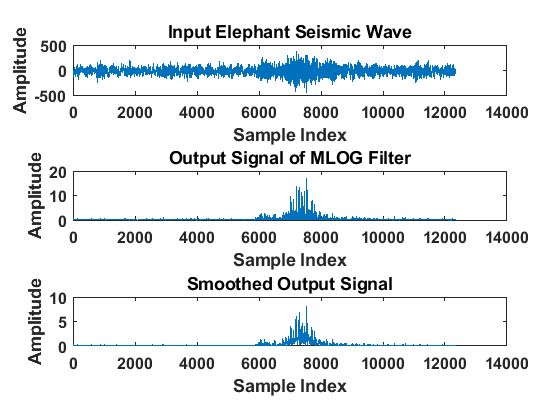

xlabel('Sample Index','FontSize',14,'FontWeight','bold')
ylabel('Amplitude','FontSize',14,'FontWeight','bold')
title('Input Elephant Seismic Wave','FontSize',14,'FontWeight','bold')
set(gca,'fontsize',12,'FontWeight','bold')
subplot(3,1,2),plot(1:length(Output), Output)
xlabel('Sample Index','FontSize',14,'FontWeight','bold')
ylabel('Amplitude','FontSize',14,'FontWeight','bold')
title('Output Signal of MLOG Filter','FontSize',14,'FontWeight','bold')
set(gca,'fontsize',12,'FontWeight','bold')
subplot(3,1,3),plot(1:length(Output_More_Smoothing), Output_More_Smoothing)
xlabel('Sample Index','FontSize',14,'FontWeight','bold')
ylabel('Amplitude','FontSize',14,'FontWeight','bold')
title('Smoothed Output Signal','FontSize',14,'FontWeight','bold')
set(gca,'fontsize',12,'FontWeight','bold')